## Specify the problem dimensions

N = 16;
aspectRatio = 1;

Lx = 100e3;
Ly = aspectRatio*100e3;
Lz = 5000;

Nx = N;
Ny = aspectRatio*N;
Nz = N+1; % 2^n + 1 grid points, to match the Winters model, but 2^n ok too.

latitude = 31;
N0 = 5.2e-3;


##  Initialize the wave model

wavemodel = InternalWaveModelConstantStratification([Lx, Ly, Lz], [Nx, Ny, Nz], latitude, N0);

Using the analytical form for constant stratification N0=0.0052


##  Make a plot showing the resolved modes *without* a maximum dOmega.

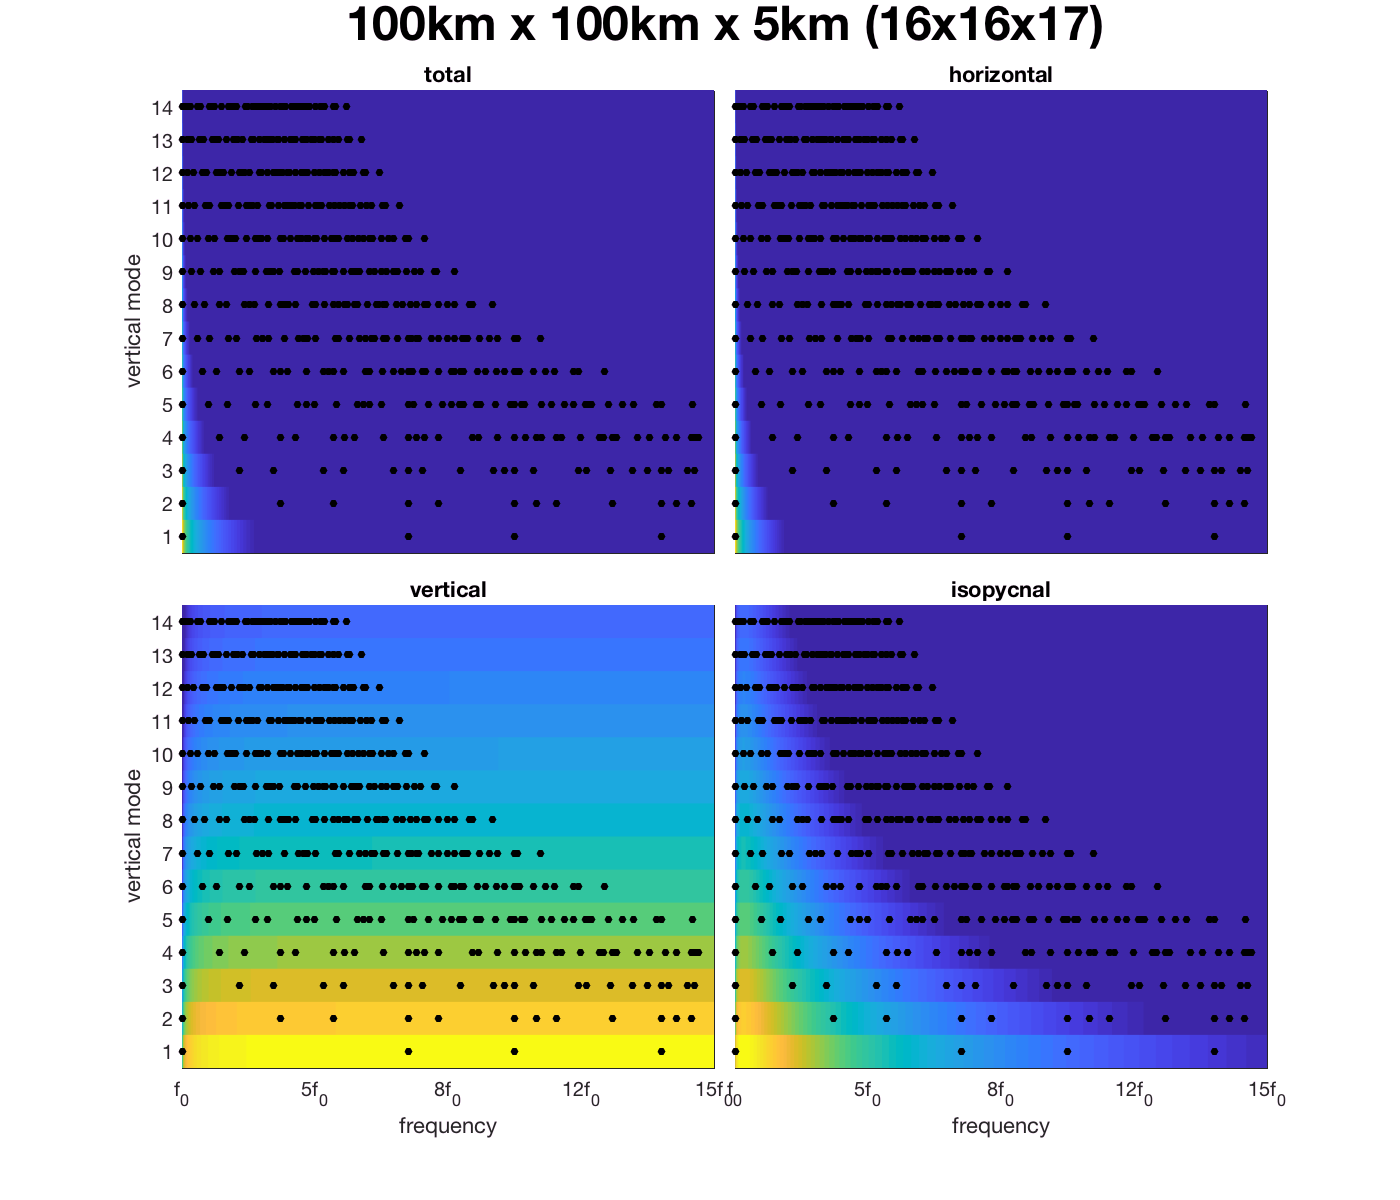

wavemodel.ShowResolvedModesPlot

##  Make a plot showing the resolved modes with a maximum wave gap of f0

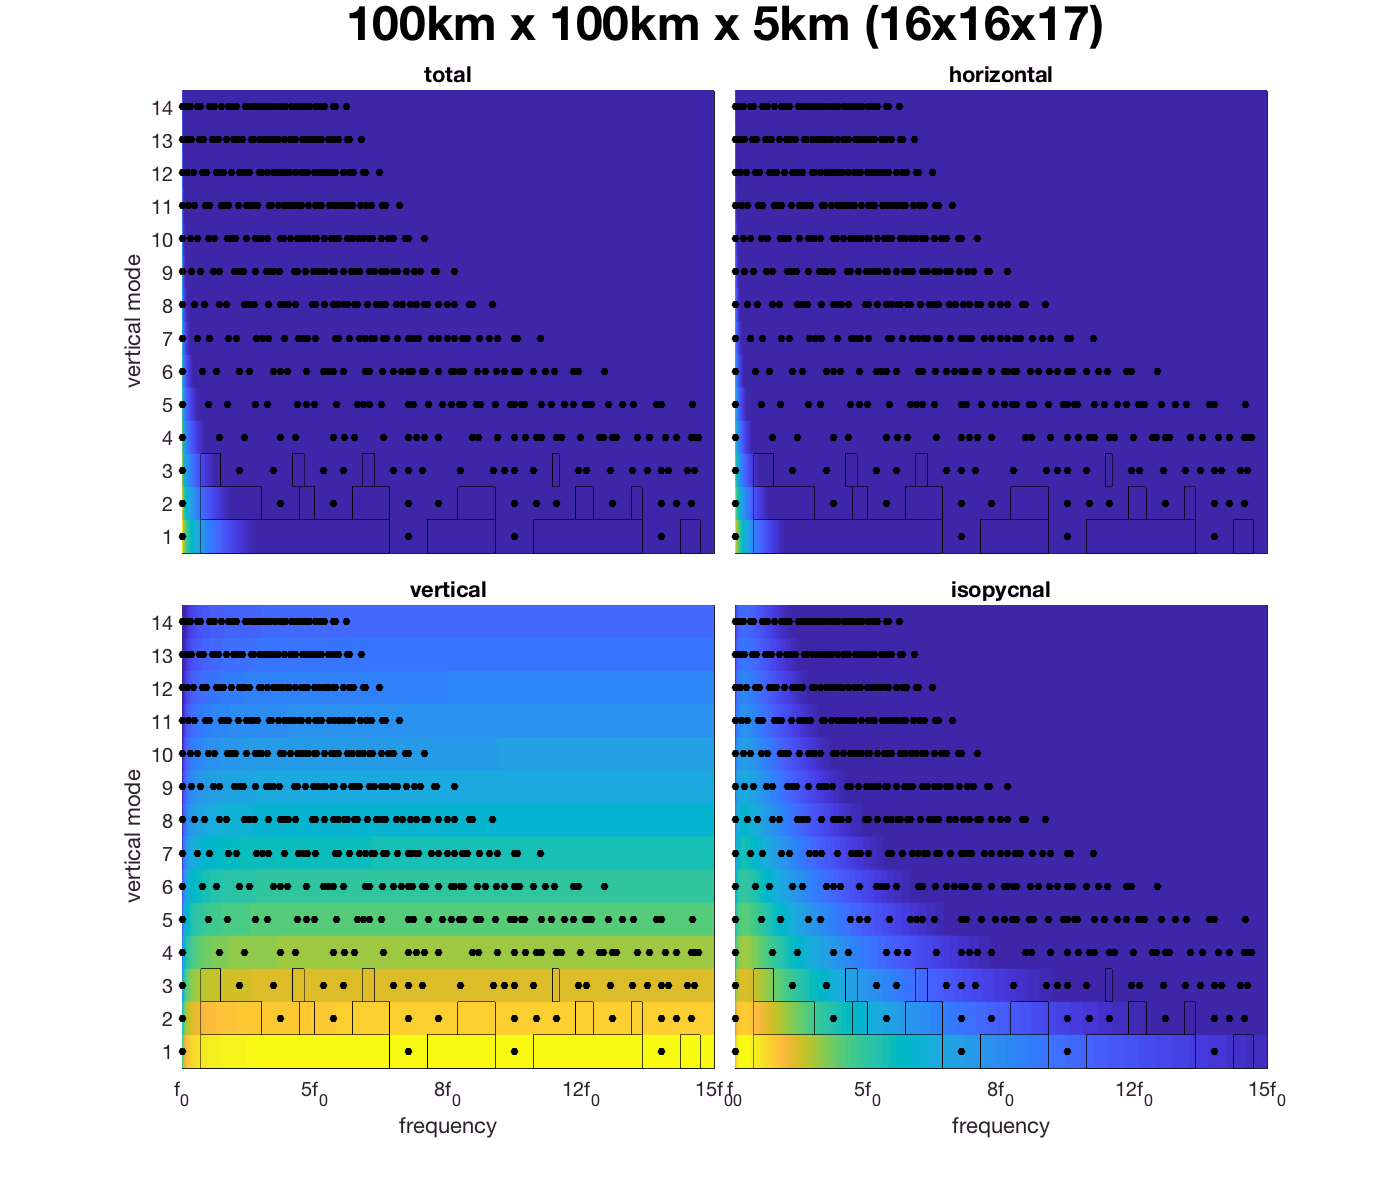


wavemodel.ShowResolvedModesPlot(wavemodel.f0)

 Notice that the boxes indicate regions where is simply left off.

## Now add in some external modes using my algorithm.

wavemodel.FillOutWaveSpectrum();

Added 115 external waves to fill out the GM spectrum.


##  Now see what the resolved modes plot looks like,

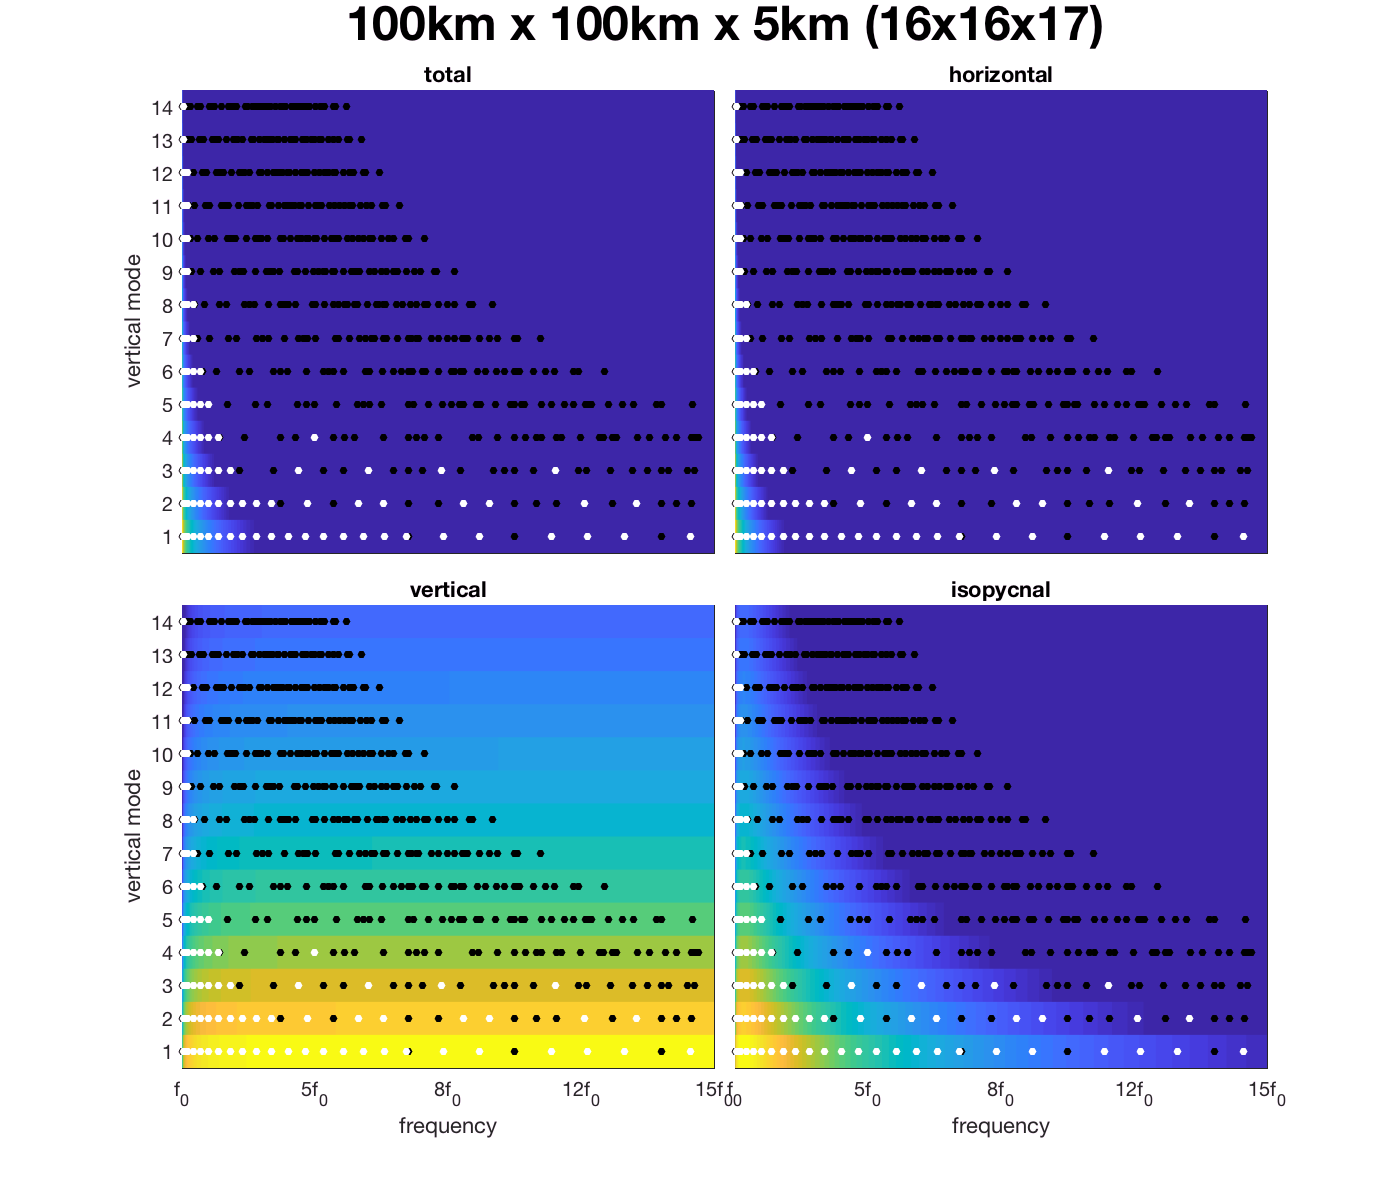

wavemodel.ShowResolvedModesPlot(wavemodel.f0)

The white dots show the external modes, the black dots are the gridded modes. There are no gaps within our criteria.

## Now we can initialize the model (with the external wave modes) and a maximum gap of f0


wavemodel.InitializeWithGMSpectrum(1.0,1.0,wavemodel.f0)

You are missing 7.68% of the energy due to limited vertical modes.
After distributing energy across frequency and mode, you still have 90.17% of reference GM energy.
Due to restricted domain size, the j=1,k=l=0 mode contains 4.90% the total energy.
The (gridded, external) wave field sums to (32.18%, 57.99%) GM given the scales, and the randomized field sums to (67.78%, 75.46%) GM


## Customize the external wave modes

We can customize the wave modes that get added. First let's remove all the wave modes, then add a custom mode at 2f0. I'm not going to give it any amplitude or phase.

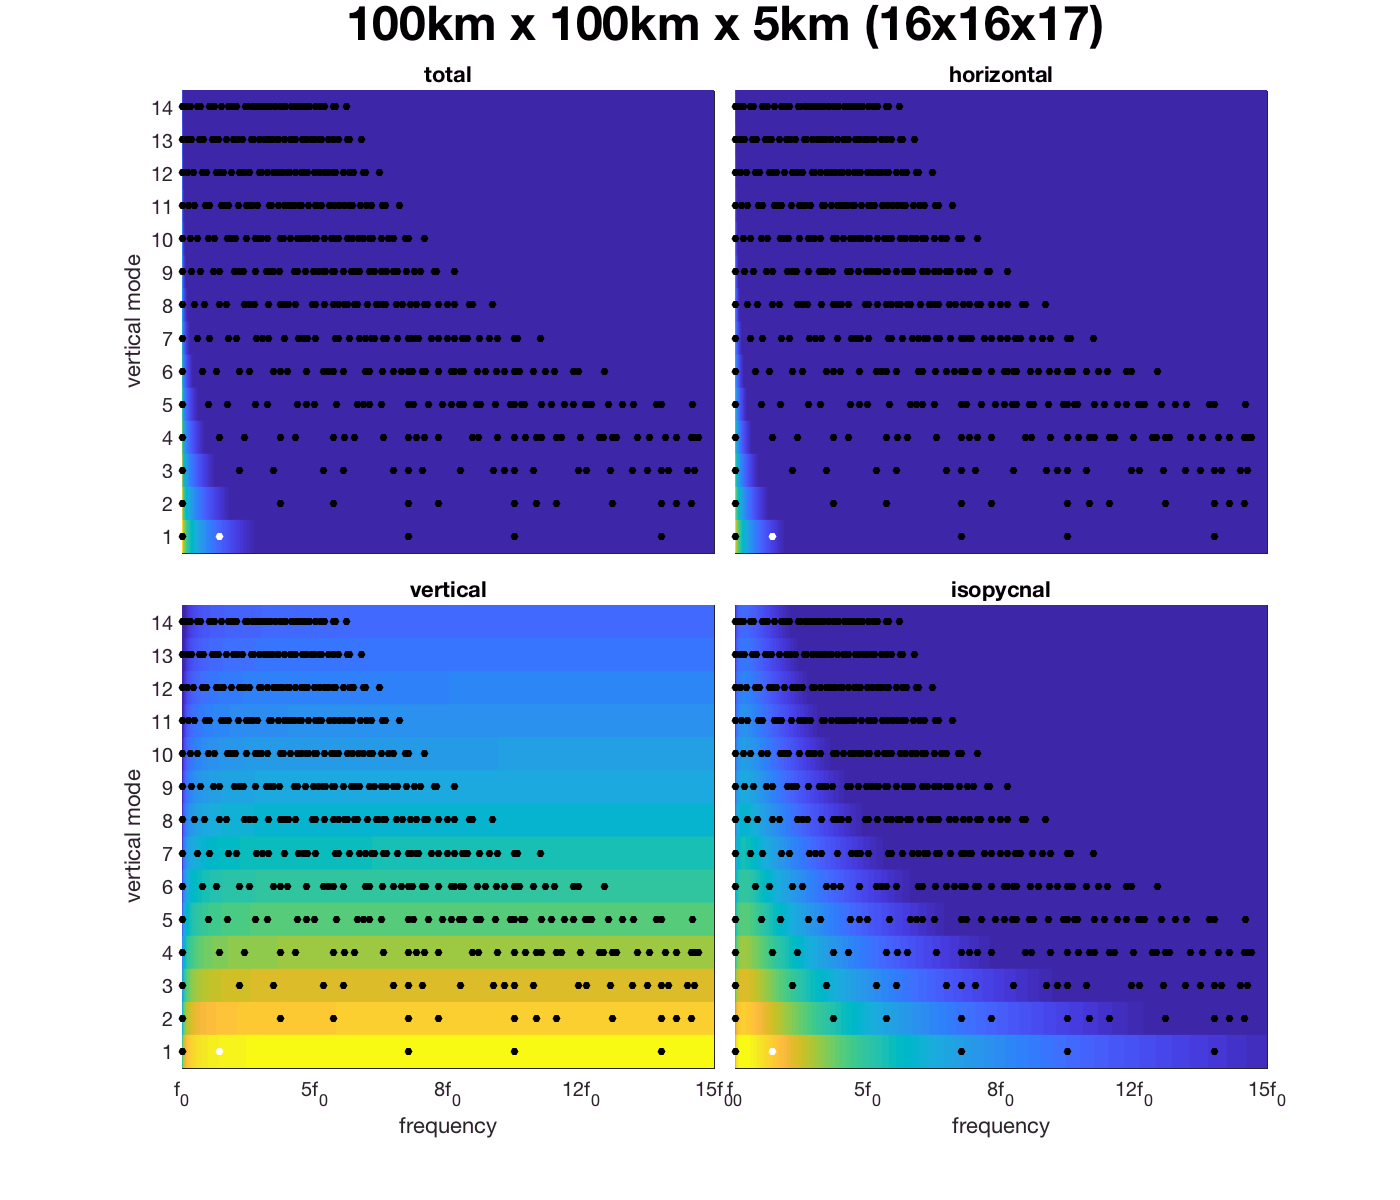

wavemodel.RemoveAllExternalWaves;
wavemodel.AddExternalWavesWithFrequencies(2*wavemodel.f0,0,1,0,0,Normalization.kConstant);
wavemodel.ShowResolvedModesPlot

Now you can see the lone external wave that we added.

## Extract all gridded waves

One cool trick is that we can extract all the gridded waves, including their amplitudes, and then feed those into this model, or some other model.

[omega, alpha, mode, phi, A] = wavemodel.WaveCoefficientsFromGriddedWaves();
wavemodelHighRes = InternalWaveModelConstantStratification([Lx/10, Ly/10, Lz], [Nx, Ny, Nz], latitude, N0);

Using the analytical form for constant stratification N0=0.0052


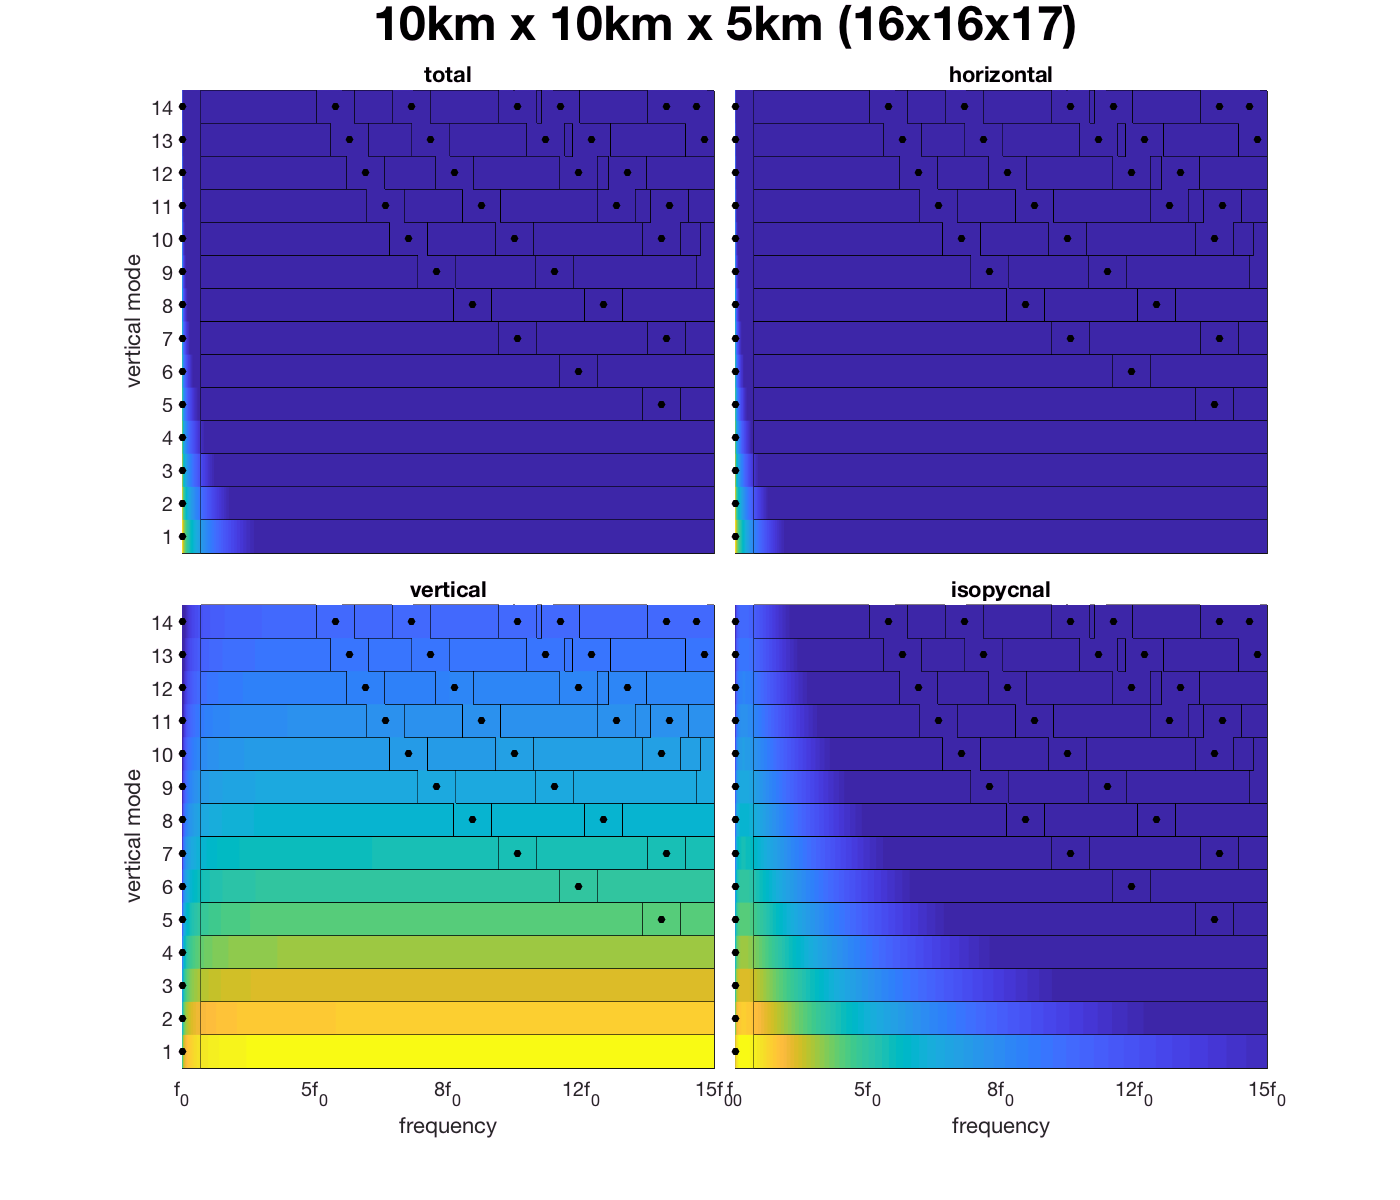

wavemodelHighRes.ShowResolvedModesPlot(wavemodel.f0)

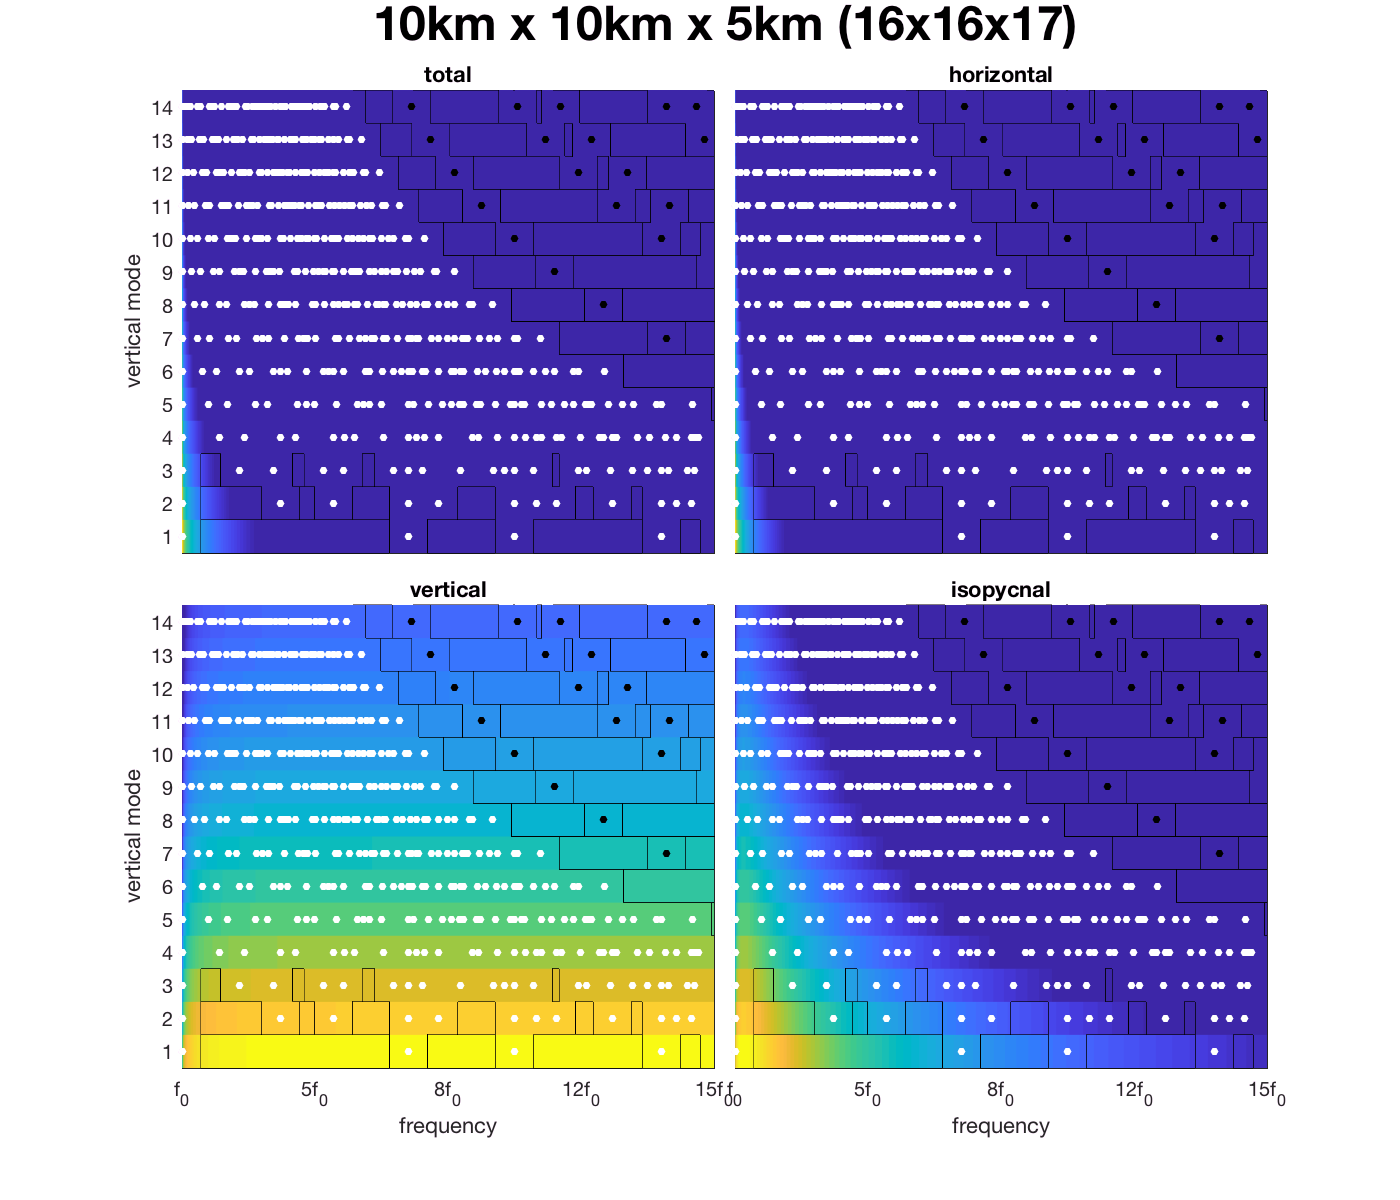

wavemodelHighRes.SetExternalWavesWithFrequencies(omega, alpha, mode, phi, A,Normalization.kConstant);
wavemodelHighRes.ShowResolvedModesPlot(wavemodel.f0)

This is just showing you the modes and the *theoretical* initialization and gaps. As it stands, only the external modes have energy (as set when we added them). If we were to initialize with the GM spectrum, those would be wiped out and given new amplitudes.